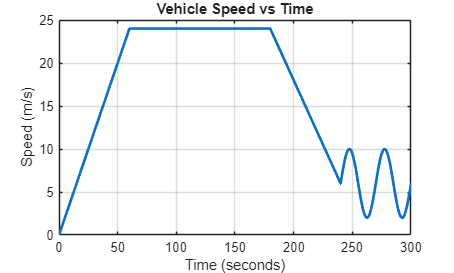

%Project 10 - Vehicle Fuel Consumption
%Benjamin Oakes - Engineering Computer Applications

% Clears all variables from the workspace
clear;

% Clears the command window
clc;

% Closes all open figure windows
close all;

% Creates a time vector from 0 to 300 seconds
time = 0:1:300;

% Creates an empty speed vector the same size as time
speed = zeros(size(time));

% Sets speed during acceleration phase from 0 to 60 seconds
speed(time <= 60) = time(time <= 60) * 0.4;

% Sets cruising speed from 61 to 180 seconds
speed(time > 60 & time <= 180) = 24;

% Sets slowing down phase from 181 to 240 seconds
speed(time > 180 & time <= 240) = 24 - 0.3 * (time(time > 180 & time <= 240) - 180);

% Sets stop-and-go phase from 241 to 300 seconds
speed(time > 240) = 6 + 4 * sin(2 * pi * (time(time > 240) - 240) / 30);

% Prevents speed from becoming negative
speed(speed < 0) = 0;

% Calculates acceleration using numerical differences
acceleration = [0 diff(speed)];

% Sets base fuel rate in liters per second
baseFuelRate = 0.0008;

% Sets fuel increase caused by speed
speedFuelFactor = 0.00005;

% Sets fuel increase caused by acceleration
accelFuelFactor = 0.0004;

% Calculates fuel consumption rate
fuelRate = baseFuelRate + speedFuelFactor .* speed + accelFuelFactor .* max(acceleration, 0);

% Calculates total fuel used over time using cumulative sum
fuelUsed = cumsum(fuelRate);

% Calculates total fuel consumed
totalFuelUsed = fuelUsed(end);

% Finds maximum speed
[maxSpeed, maxSpeedIndex] = max(speed);

% Finds time when maximum speed occurs
maxSpeedTime = time(maxSpeedIndex);

% Finds maximum fuel consumption rate
[maxFuelRate, maxFuelIndex] = max(fuelRate);

% Finds time when fuel consumption rate is highest
maxFuelTime = time(maxFuelIndex);

% Creates first figure
figure;

% Plots vehicle speed over time
plot(time, speed, 'LineWidth', 2);

% Turns grid on
grid on;

% Adds graph title
title('Vehicle Speed vs Time');

% Labels x-axis
xlabel('Time (seconds)');

% Labels y-axis
ylabel('Speed (m/s)');

% Saves figure as image
saveas(gcf, 'project19_speed_vs_time.png');

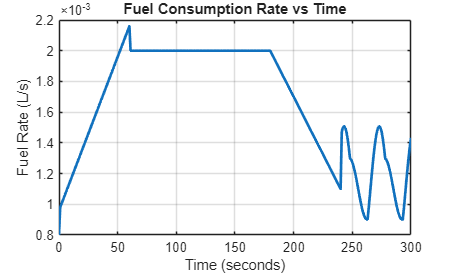


% Creates second figure
figure;

% Plots fuel consumption rate over time
plot(time, fuelRate, 'LineWidth', 2);

% Turns grid on
grid on;

% Adds graph title
title('Fuel Consumption Rate vs Time');

% Labels x-axis
xlabel('Time (seconds)');

% Labels y-axis
ylabel('Fuel Rate (L/s)');

% Saves figure as image
saveas(gcf, 'project19_fuel_rate.png');

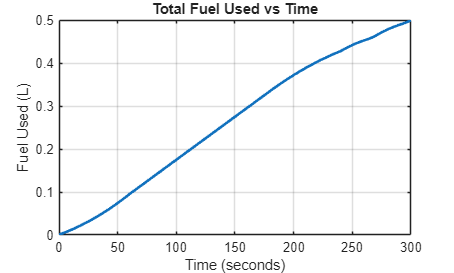


% Creates third figure
figure;

% Plots total fuel used over time
plot(time, fuelUsed, 'LineWidth', 2);

% Turns grid on
grid on;

% Adds graph title
title('Total Fuel Used vs Time');

% Labels x-axis
xlabel('Time (seconds)');

% Labels y-axis
ylabel('Fuel Used (L)');

% Saves figure as image
saveas(gcf, 'project19_total_fuel_used.png');


% Creates results table
resultsTable = table(time', speed', acceleration', fuelRate', fuelUsed', ...
    'VariableNames', ...
    {'Time_seconds', 'Speed_mps', 'Acceleration_mps2', 'FuelRate_Lps', 'FuelUsed_L'});

% Displays table in command window
disp(resultsTable);

    Time_seconds    Speed_mps    Acceleration_mps2    FuelRate_Lps    FuelUsed_L
    ____________    _________    _________________    ____________    __________

          0               0                   0            0.0008       0.0008  
          1             0.4                 0.4           0.00098      0.00178  
          2             0.8                 0.4             0.001      0.00278  
          3             1.2                 0.4           0.00102       0.0038  
          4             1.6                 0.4           0.00104      0.00484  
          5               2                 0.4           0.00106       0.0059  
          6             2.4                 0.4           0.00108      0.00698  
          7             2.8                 0.4            0.0011      0.00808  
          8        


% Displays total fuel used
fprintf('Total fuel used over the driving cycle is %.4f liters.\n', totalFuelUsed);

Total fuel used over the driving cycle is 0.4999 liters.



% Displays maximum speed
fprintf('Maximum speed is %.2f m/s at %.0f seconds.\n', maxSpeed, maxSpeedTime);

Maximum speed is 24.00 m/s at 60 seconds.



% Displays maximum fuel rate
fprintf('Maximum fuel consumption rate is %.5f L/s at %.0f seconds.\n', maxFuelRate, maxFuelTime);

Maximum fuel consumption rate is 0.00216 L/s at 60 seconds.
